syms m th w thp wp g l a k ta 
m=1;
g=9.81;
l=0.1;
a=l/2;
k=0.1;
%%%%%%%%%%%%%%%%%%
thp=w;
wp=(1/(m*l^2))*(ta-2*k*a*a*(sin(th)*cos(th))-l*m*g*sin(th));
xe=[w th];
y=th;
A=jacobian([wp,thp],xe)

$$A = \left(\begin{array}{cc} 0 & -\frac{{\cos\left(\mathrm{th}\right)}^{2}}{20}-\frac{981\,\cos\left(\mathrm{th}\right)}{10}+\frac{{\sin\left(\mathrm{th}\right)}^{2}}{20}\\ 1 & 0 \end{array}\right)$$

B=jacobian([wp,thp],ta)

$$B = \left(\begin{array}{c} 100\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

D=jacobian(y,ta)

$$D = 0$$

%P.op
th=pi/3

th = 1.0472

%%%%%%%%%%%%%%%%%%%
A=double(eval(A))

A =          0  -49.0250
    1.0000         0


B=double(eval(B))

B =    100
     0


C=double(eval(C))

C =      0     1


D=double(eval(D))

D = 0

[num,den]=ss2tf(A,B,C,D)

num =      0     0   100


den =     1.0000         0   49.0250


ft=tf(num,den)

ft =
 
      100
  -----------
  s^2 + 49.03
 
Continuous-time transfer function.



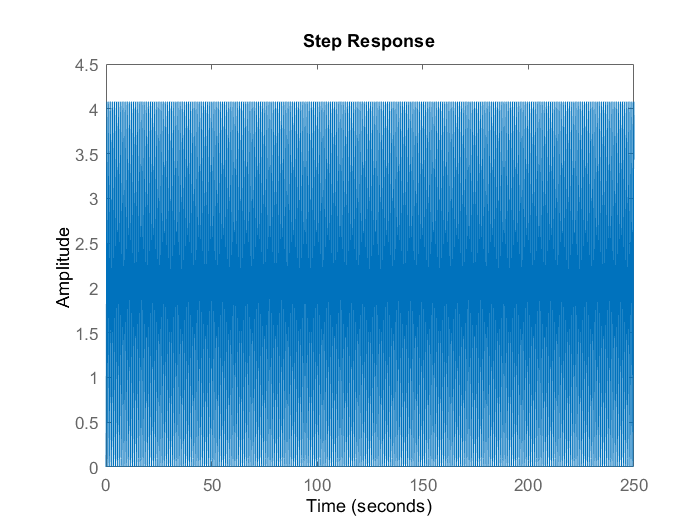

step(ft)

%%%%%%%%%%%%%%%%%%
ts=3

ts = 3

zeta=0.8

zeta = 0.8000

wn=4/(ts*zeta)

wn = 1.6667

polos=roots([1 2*wn*zeta wn^2])

polos =   -1.3333 + 1.0000i
  -1.3333 - 1.0000i


K=acker(A,B,polos)

K =     0.0267   -0.4625


%PARA ESS=0
polosEss=conv(polos,[1 5*zeta*wn])

polosEss =   -1.3333 + 1.0000i -10.2222 + 5.6667i  -8.8889 - 6.6667i


Aempaq=[A(1,1),A(1,2),0;A(2,1),A(2,2),0;-C(1,1),-C(1,2),0]

Aempaq =          0  -49.0250         0
    1.0000         0         0
         0   -1.0000         0


Bempaq=[B(1,1);B(2,1);0]

Bempaq =    100
     0
     0


Cempaq=[C(1,1),C(1,2),0]

Cempaq =      0     1     0


K1=acker(Aempaq,Bempaq,polosEss)

K1 =     0.2044    1.0610   -1.8930


%%%% OBSERVADOR %%%%
tsa=ts/10;
wna=4/(tsa*zeta)

wna = 16.6667

obs=[C;C*A]

obs =      0     1
     1     0


det(obs)

ans = -1

pdo=conv([1 2*tsa*zeta wna^2],[1 10*wna*zeta])

pdo = 	1.0e+04 *

    0.0001    0.0134    0.0342    3.7037


phia= A^3+pdo(2)*A^2+pdo(3)*A+pdo(4)*eye(2)

phia = 	1.0e+04 *

    3.0477   -1.4352
    0.0293    3.0477


L=phia*(inv(obs))*[0;1]

L = 	1.0e+04 *

    3.0477
    0.0293



%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% CON DELAY 1s %%%%%%%%%
tm=1

tm = 1

polosEssT=conv(polosEss,[1 10*wn*zeta])

polosEssT = 	1.0e+02 *

  -0.0133 + 0.0100i  -0.2800 + 0.1900i  -1.4519 + 0.6889i  -1.1852 - 0.8889i


polosEssT=conv(polosEssT,[1 10*wn*zeta])

polosEssT = 	1.0e+03 *

  -0.0013 + 0.0010i  -0.0458 + 0.0323i  -0.5185 + 0.3222i  -2.0543 + 0.8296i  -1.5802 - 1.1852i


ftdelay=tf([1],[(tm^2)/2 tm 1])

ftdelay =
 
         1
  ---------------
  0.5 s^2 + s + 1
 
Continuous-time transfer function.



ft2=ft*ftdelay

ft2 =
 
                      100
  -------------------------------------------
  0.5 s^4 + s^3 + 25.51 s^2 + 49.03 s + 49.03
 
Continuous-time transfer function.



[A1,B1,C1,D1]=tf2ss([0.5,5.747],[0.245,4.251,14.7,24.64,14.49])

A1 =   -17.3510  -60.0000 -100.5714  -59.1429
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B1 =      1
     0
     0
     0


C1 =          0         0    2.0408   23.4571


D1 = 0

Aempaq1=[A1(1,1),A1(1,2),A1(1,3),A1(1,4),0;A1(2,1),A1(2,2),A1(2,3),A1(2,4),0;A1(3,1),A1(3,2),A1(3,3),A1(3,4),0;A1(4,1),A1(4,2),A1(4,3),A1(4,4),0;-C1(1,1),-C1(1,2),-C1(1,3),-C1(1,4),0]

Aempaq1 =   -17.3510  -60.0000 -100.5714  -59.1429         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0   -2.0408  -23.4571         0


Bempaq1=[B1(1,1);B1(2,1);B1(3,1);B1(4,1);0]

Bempaq1 =      1
     0
     0
     0
     0


KDelay=acker(Aempaq1,Bempaq1,polosEssT)

KDelay = 	1.0e+10 *

    0.0000    0.0006    0.2853    9.4216   -0.0170
